## Preperation:

Before we satrt generating the signals and detect the targert, we define the radar specifications.

%% Radar Specifications 
%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Frequency of operation = 77GHz
% Max Range = 200m
% Range Resolution = 1 m
% Max Velocity = 100 m/s
%%%%%%%%%%%%%%%%%%%%%%%%%%%

definisitons of Radar specifications.

lightSpeed= 3e8;    %speed of light [m/s]
d_res= 1;           %distance resolution [m]
max_r= 200;         %maximum range [m]
max_vel = 100;      %maximum velocity [m/s]
fc= 77e9;            %operation frequency [Hz]
pos = 100;           %Target distance [m]
vel = 40;           %Target velocity [m/s]
fprintf("Range = %0.1f [m]\nVelocity = %.2f [m/s]\n\n", pos, vel);

Range = 100.0 [m]
Velocity = 40.00 [m/s]



isPlotDetails = true;
isPlotResult = true;

In the last code snippet there are extra variables defined. like the target distance and the target velocity.

## **Design the FMCW waveform**

The next step is to calculate the FMCW charachtaristcs (chirp time, band width and the slop).

B= lightSpeed / (2 * d_res);       %Bandwidth [Hz]
Tchirp= 5.5*2*max_r/lightSpeed;    %Chirp Time [s]
slop= B / Tchirp;                  %slop [Hz/s]
fprintf("Bandwidth = %e\nT_sweep = %e\nslop = %e\n\n", B, Tchirp, slop); 

Bandwidth = 1.500000e+08
T_sweep = 7.333333e-06
slop = 2.045455e+13



Then we define the number of cells for range and doppler.

%The number of chirps in one sequence. Its ideal to have 2^ value for the ease of running the FFT
%for Doppler Estimation. 
Nd=128;                   % #of doppler cells OR #of sent periods % number of chirps

%The number of samples on each chirp. 
Nr=1024;                  %for length of time OR # of range cells

After that we define the time stamp.

% Timestamp for running the displacement scenario for every sample on each
% chirp
t=linspace(0,Nd*Tchirp,Nr*Nd); %total time for samples

The next step is to initialize the transmitted and the the recieved signals (Tx and Rx). We also initialize the mixed signal, which is the result of multiplying the Tx and Rx signals and represents the beat frequency. We need also time delay vector, which represents the time difference between Tx and Rx.

%Creating the vectors for Tx, Rx and Mix based on the total samples input.
Tx=zeros(1,length(t)); %transmitted signal
Rx=zeros(1,length(t)); %received signal
Mix = zeros(1,length(t)); %beat signal

%Similar vectors for time delay.
td=zeros(1,length(t));

After the initialization we calculate the signals.

%% Signal generation and Moving Target simulation
% Running the radar scenario over the time. 
%fb = 2*(slop*pos + fc*vel)/lightSpeed;
td = 2*((pos-t.*vel))./lightSpeed;
Tx = cos(2*pi*(t.*fc + ((t.^2).*slop)/2));
Rx = cos(2*pi*((t-td).*fc + ((t-td).^2).*slop./2));
Mix = times(Tx,Rx);

Show the results for the Tx, Rx, and the mixed signal (beat frequency).

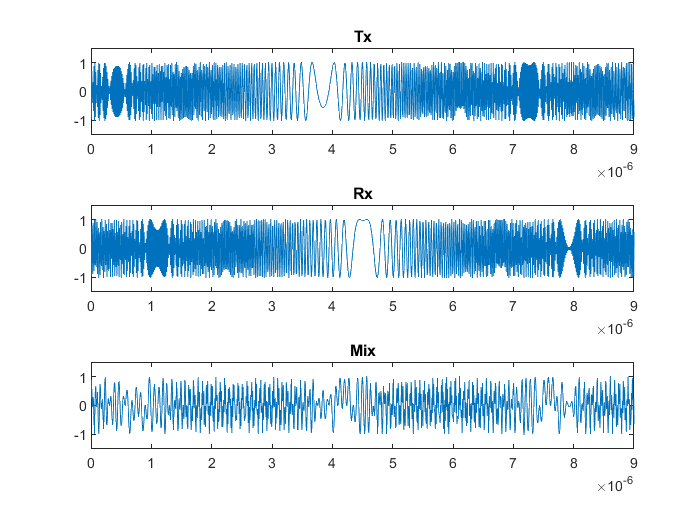

if isPlotDetails
    subplot(3,1,1)
    plot(t, Tx);
    title("Tx");
    axis ([0 9e-6 -1.5 1.5]);
    subplot(3,1,2)
    plot(t, Rx);
    title("Rx");
    axis ([0 9e-6 -1.5 1.5]);
    subplot(3,1,3)
    plot(t, Mix);
    title("Mix");
    axis ([0 9e-6 -1.5 1.5]);
end

## Applying one dimensional Fourier Transform:

To calculate the range of target we apply FFT (Fast Fourier Transform) for the mixed signal.

%% RANGE MEASUREMENT

 % *%TODO* :
%reshape the vector into Nr*Nd array. Nr and Nd here would also define the size of
%Range and Doppler FFT respectively.
Mix2d = reshape(Mix, [Nr,Nd]);

 % *%TODO* :
%run the FFT on the beat signal along the range bins dimension (Nr) and
%normalize.
Mix_fft = fft(Mix2d,Nr,1);
 % *%TODO* :
% Take the absolute value of FFT output
Mix_fft = abs(Mix_fft/Nr);
 % *%TODO* :
% Output of FFT is double sided signal, but we are interested in only one side of the spectrum.
% Hence we throw out half of the samples.
Mix_fft = Mix_fft(1:Nr/2+1);

Plot the result of the FFT.

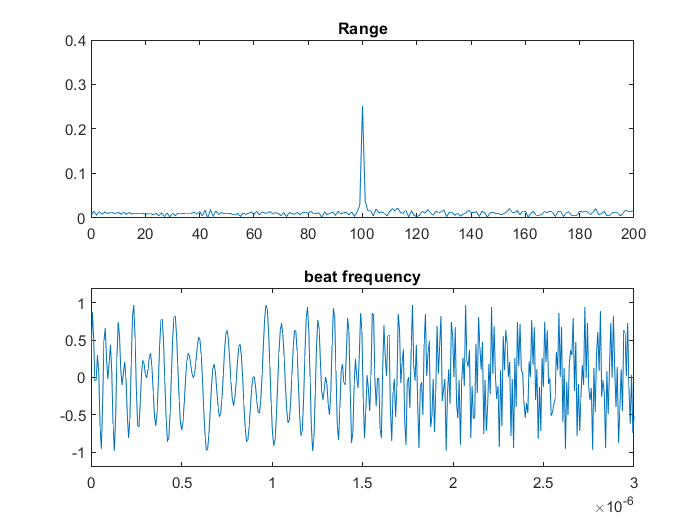

if isPlotDetails
     %plotting the range
     figure ('Name','Range from First FFT');
     subplot(2,1,1)

    % *%TODO* :
    % plot FFT output 
     plot(0:Nr/2,Mix_fft);
     title("Range")
     axis ([0 200 0 0.4]);
     subplot(2,1,2);
     plot(t, Mix);
     title("beat frequency");
     axis ([0 3e-6 -1.2 1.2]);
 end

## Applying 2 dimensional Fourier Transform:

To get the range/doppler map we reshape the mixed signal to 2 dimesional matrix, then we apply the 2 dimensional fast fourier transform.

 % Range Doppler Map Generation.

% The output of the 2D FFT is an image that has reponse in the range and
% doppler FFT bins. So, it is important to convert the axis from bin sizes
% to range and doppler based on their Max values.

Mix=reshape(Mix,[Nr,Nd]);

% 2D FFT using the FFT size for both dimensions.
sig_fft2 = fft2(Mix,Nr,Nd);

% Taking just one side of signal from Range dimension.
sig_fft2 = sig_fft2(1:Nr/2,1:Nd);
sig_fft2 = fftshift (sig_fft2);
RDM = abs(sig_fft2);
RDM = 10*log10(RDM) ;

Show the result range/doppler map.

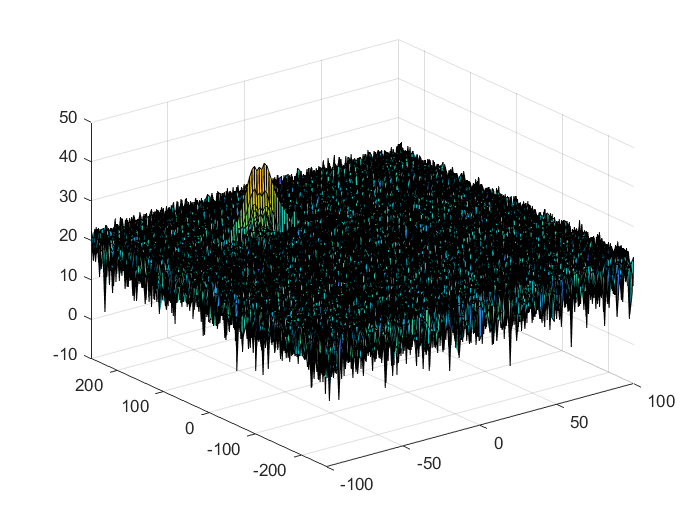

%use the surf function to plot the output of 2DFFT and to show axis in both
%dimensions
doppler_axis = linspace(-100,100,Nd);
range_axis = linspace(-200,200,Nr/2)*((Nr/2)/400);
if isPlotDetails
    figure,surf(doppler_axis,range_axis,RDM);
end

## CFAR Implementation:

By implemeting CFAR, the CA-CFAR method is is choosen to use in this section.

The first step is to define the number of the training cells and the guard cells. After that we calculate the size of the block.

The numbers of training cells and guard cells are choosen after testing the results.

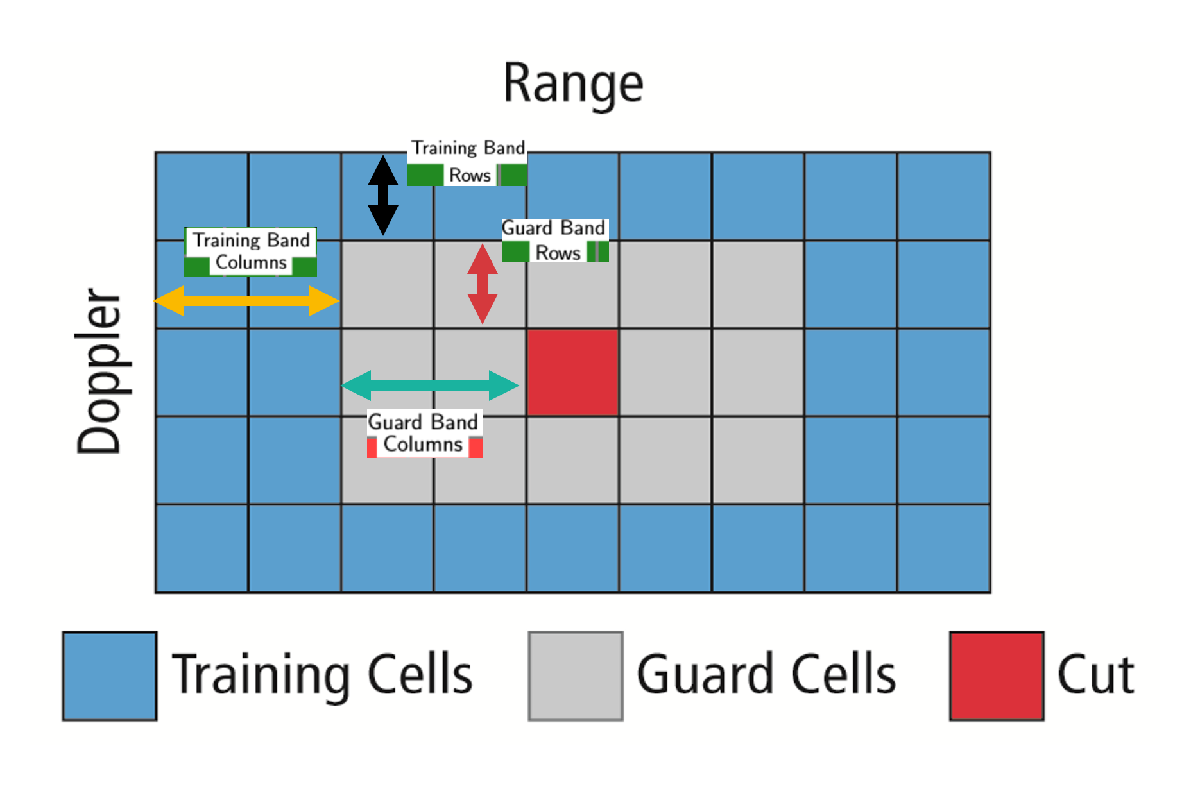

% *%TODO* :
%Select the number of Training Cells in both the dimensions.
Tr = 8;
Td = 8;
% *%TODO* :
%Select the number of Guard Cells in both dimensions around the Cell under 
%test (CUT) for accurate estimation
Gr = 2;
Gd = 2;
gridWidth = 2*(Tr + Gr) + 1;
gridHeight = 2*(Td + Gd) + 1;

Then we define the offset of the threshold. After testing the results the choosen value is 7. Heigher values will cut the signal and lower values will not cut out the noise correctly.

% *%TODO* :
% offset the threshold by SNR value in dB
offset = 7;

In the following we initialize a matrix that contains zero values and has the same size of the range/doppler map. This matix saves the results of the CFAR calculations.

% *%TODO* :
%Create a vector to store noise_level for each iteration on training cells
%noise_level = zeros(1,length(t));
signal_cfar = zeros(size(RDM));

In the following snippet is the implementation of CFAR algorithm.

% *%TODO* :
%design a loop such that it slides the CUT across range doppler map by
%giving margins at the edges for Training and Guard Cells.
%For every iteration sum the signal level within all the training
%cells. To sum convert the value from logarithmic to linear using db2pow
%function. Average the summed values for all of the training
%cells used. After averaging convert it back to logarithimic using pow2db.
%Further add the offset to it to determine the threshold. Next, compare the
%signal under CUT with this threshold. If the CUT level > threshold assign
%it a value of 1, else equate it to 0.


   % Use RDM[x,y] as the matrix from the output of 2D FFT for implementing
   % CFAR
for i = 1:size(RDM,1)- gridWidth/2  %iterate throw the range dimension
    for j = 1:size(RDM,2) - gridHeight/2  %iterate throw the doppler dimension
        if(i<gridWidth/2 || j<gridHeight/2)
            continue;
        end
        subMat = RDM(i-(gridWidth - 1)/2:i+(gridWidth-1)/2 ,j-(gridHeight-1)/2:j+(gridHeight-1)/2);
        linearValues = db2pow(subMat);
        average = sum(sum(linearValues))/(gridWidth*gridHeight);
        threshold = pow2db(average)+offset;
        if(RDM(i,j)<threshold)
            signal_cfar(i,j)=0;
        else
            signal_cfar(i,j)=1;
        end
    end
end

Show the results.

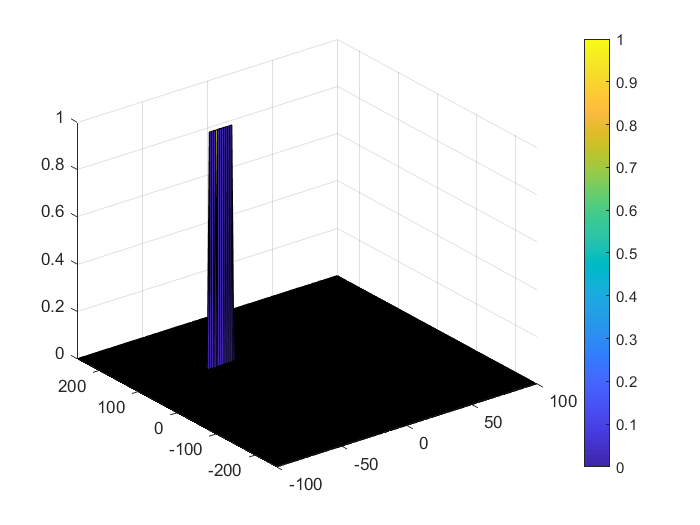

% *%TODO* :
%display the CFAR output using the Surf function like we did for Range
%Doppler Response output.
if isPlotResult
    figure,surf(doppler_axis,range_axis,signal_cfar);
    colorbar;
end